# **Deep Learning for Signal Data**

**This demo shows how you can build a model using transfer learning techniques to classify signal data. We will use Wavelet Transform to generate a time-frequency representation of a signal.  **

**The Wavelet Transform greatly enhances the spectral information present as a function of time in the signal and we can save this information as a Image**

# **Steps**:

- **Explore the Signals**

- **Generate Wavelet Time-Frequency Representations**

- **Train a Pre-Trained Network (AlexNet)**

- **Evaluate the trained model**

# **Explore the Signals**

## Load Signals

load 'MAT Files\ECGData.mat';

size(ECGData.Data)

ans =          162       65536


ARR = Arrythmia, CHF = Congestive heart failure, NSR = Normal sinus rythm

## Visualize Signals 

signalAnalyzer

## Challenges with Traditional Time Frequency Analysis Approach

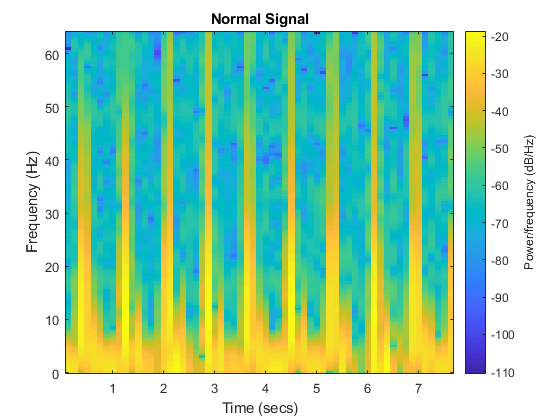

Fs = 128;
figure;
spectrogram(Normal_Sample,32,[],[],Fs,'yaxis'); title('Normal Signal');

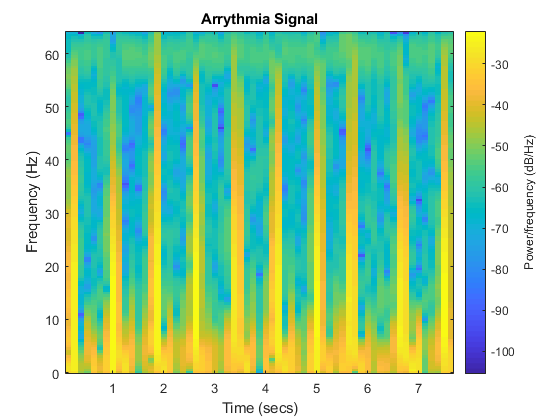

figure;
spectrogram(Arrythmia_Sample,32,[],[],Fs,'yaxis'); title('Arrythmia Signal');

Notice although the signals have different meaning, a traditional time-frequency anlaysis does not help identify the difference between the two signals

##  Time Frequency Analysis using Wavelets

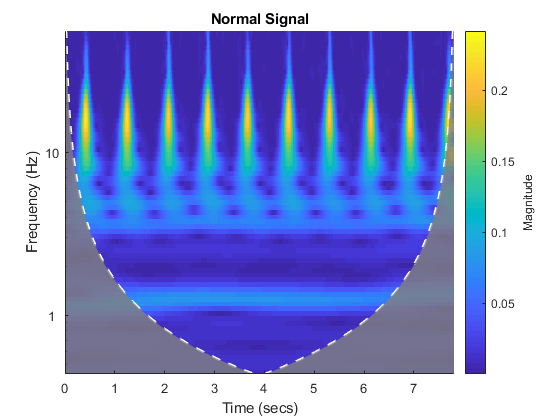

figure;
subplot(1,2,1)
cwt(Normal_Sample,Fs); title('Normal Signal');

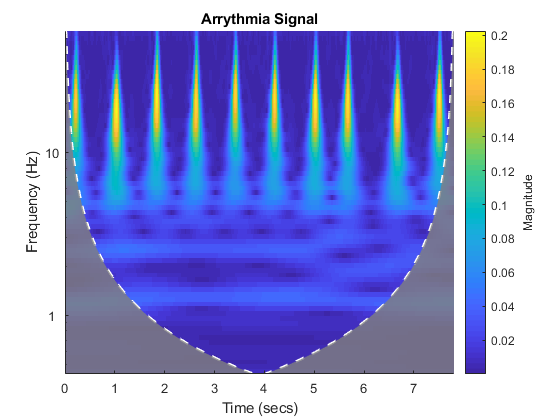

subplot(1,2,2)
cwt(Arrythmia_Sample,Fs); title('Arrythmia Signal');

Notice how the spectral details have been enhanced with the Wavelet Transform. For instance,  

- The peaks are well separated 

- The irregular separation of the yellow bars distinguishes the  Arrythmia Signal from the Normal Signal

- There is some activity going on in the lower half of the representation for Arrythmia which is not the case with the Normal Signal

**We can save these representations as images (.jpg) and train a preconfigured Convolutional Neural Network**

# **Generate Wavelet Time-Frequency Representations**

## Create a Filter Bank

If we want to compute the wavelet transform on multiple signals, using a precomputed filter bank  can greatly speed up the process 

sig = ECGData.Data(1,:);
signalLength = length(sig);
Fs = 128; % normal for ECG
fb = cwtfilterbank('SignalLength',signalLength,'SamplingFrequency',Fs,'VoicesPerOctave',48); % 48 - we get a sharp time-frequency representation 

Present a high fidelity (resolution) representation to a deep network so that it can find the features. 

Labels: NSR - normal sinus rythm, ARR - arrythmia, CHF - congestive heart failure

## Compute the Wavelet Transform 

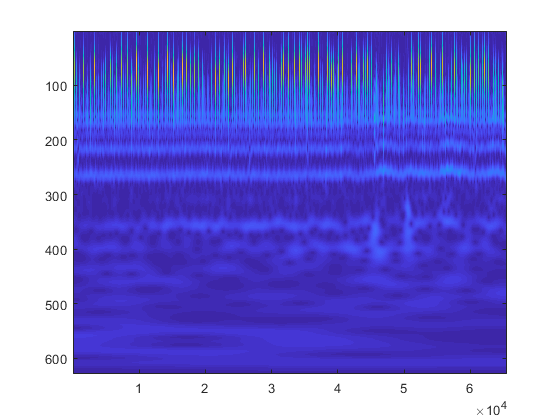

[wt,f] = cwt(sig,'Filterbank',fb);
imagesc(abs(wt))

**Generate Time-Frequency Visualizations for all Signals**

%edit('createRGBfromTF.m')
%edit('saveTimeFrequencyRep.m')
createRGBfromTF(ECGData)

implay('tf.mp4');

plotting log2(f) vs abs(wt)

## Split the Time-Frequency Representation Images into Training and Test Sets

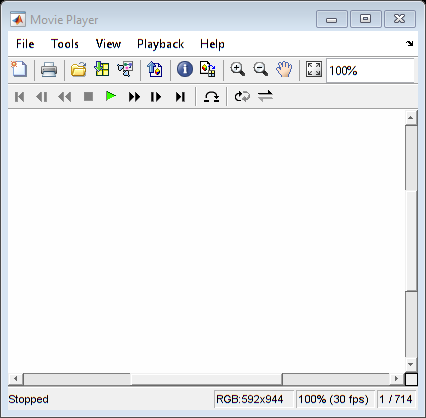

rootFolder = pwd;

folderName = 'data';

allImages = imageDatastore(strcat(rootFolder,filesep,folderName), 'IncludeSubfolders', true,...
    'LabelSource', 'foldernames');

[trainingImages, testImages] = splitEachLabel(allImages, 0.8, 'randomize');

# **Train a Pre-Trained Network (AlexNet)**

## **Initialize the Network**

Import AlexNet, then replace layers 23 and 25 with new ones.

alex = alexnet(); 
layers = alex.Layers
layers(23) = fullyConnectedLayer(3); % change this based on # of classes
layers(25) = classificationLayer;

## **Train the network**

Transfer-learn the re-configured network. First, define training options.

ilr = 0.0001;
mxEpochs = 12;

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    

mbSize =10;
opts = trainingOptions('sgdm', 'InitialLearnRate', ilr, ...
    'MaxEpochs',mxEpochs , 'MiniBatchSize',mbSize, ...
    'Plots', 'training-progress');

trainingImages.ReadFcn = @readFunctionTrain;

myNet = trainNetwork(trainingImages, layers, opts);

Training on GPU: 50 sek

Training on CPU: 3 min 50 sek 

[](http://\\fs-58-ah\vmgr$\home08\kdevleke\Documents\MATLAB\Deep-Learning-for-Signals\tf.mp4)

# **Evaluate the Trained Model**

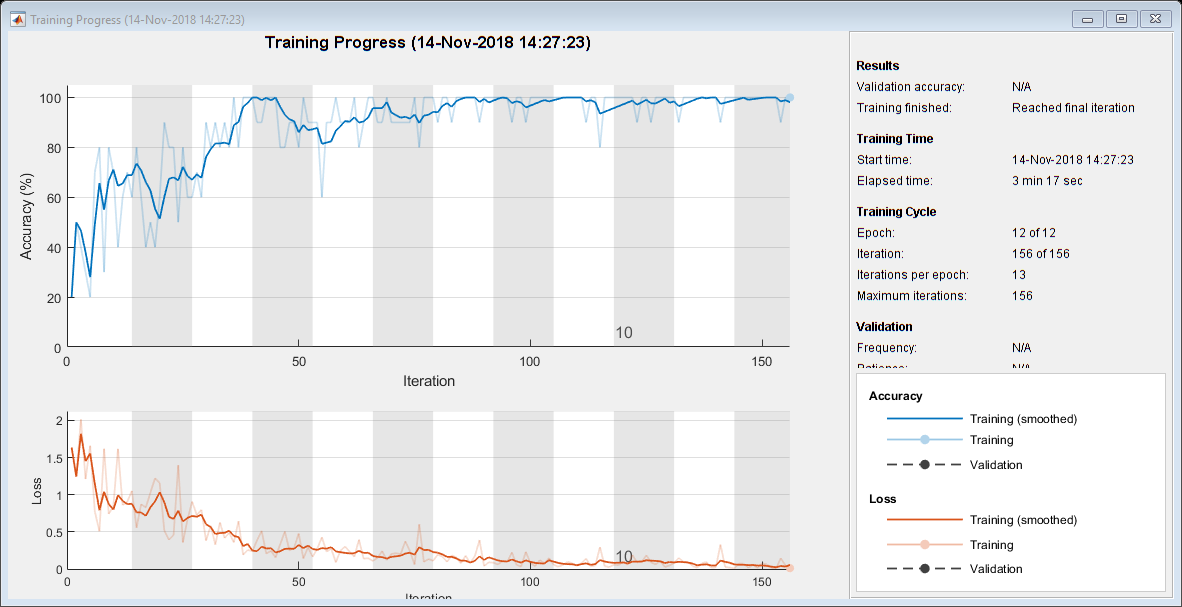

Training on single CPU.


Initializing image normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       20.00% |       1.6348 |      1.0000e-04 |
|       4 |          50 |       00:01:02 |       80.00% |       0.4784 |      1.0000e-04 |
|       8 |         100 |       00:02:05 |      100.00% |       0.0783 |      1.0000e-04 |
|      12 |         150 |       00:03:08 |      100.00% |       0.0792 |      1.0000e-04 |
|      12 |         156 |       00:03:17 |      100.00% |       0.0138 |      1.0000e-04 |
|========================================================================================|


if ~exist('myNet','var')
    load myNet.mat
end

% Define function to read (and resize) test images
testImages.ReadFcn = @readFunctionTrain;

% Classify the test images. Note that we can use the imageDatastore

accuracy = 0.9375

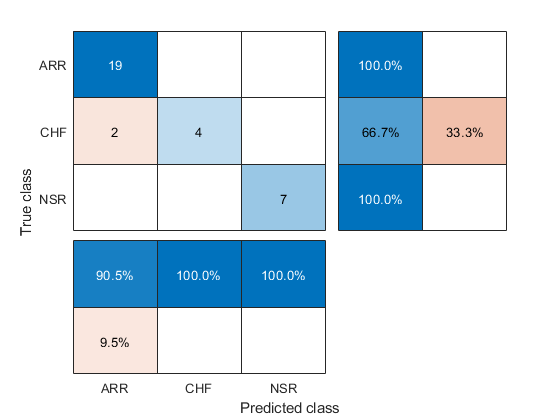

% directly - we don't have to read images into memory - this is done
% automatically when classifying images.
predictedLabels = classify(myNet, testImages);
accuracy = mean(predictedLabels == testImages.Labels)

% Create confusionchart
cm = confusionchart(testImages.Labels,predictedLabels);
cm.ColumnSummary = 'column-normalized';
cm.RowSummary = 'row-normalized';